请选择参数输入方式：
1. 使用默认参数
2. 自定义输入参数


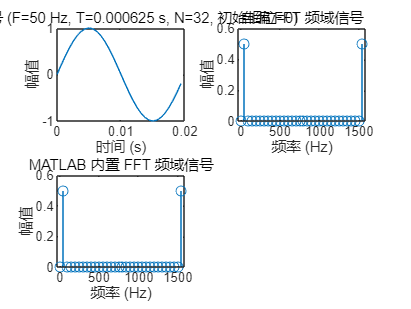

最大差异: 5.463e-15


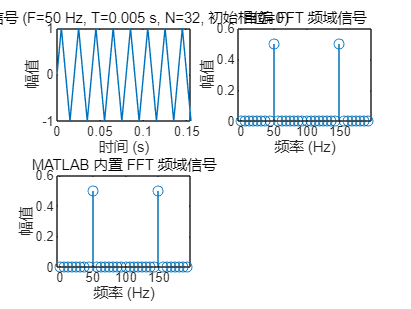

最大差异: 9.7972e-16


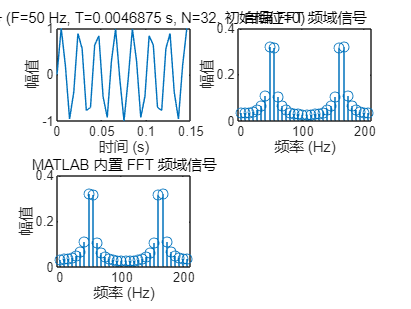

最大差异: 2.5121e-15


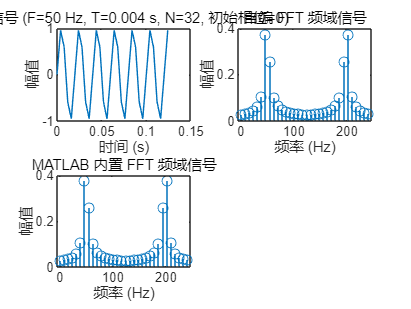

最大差异: 2.5121e-15


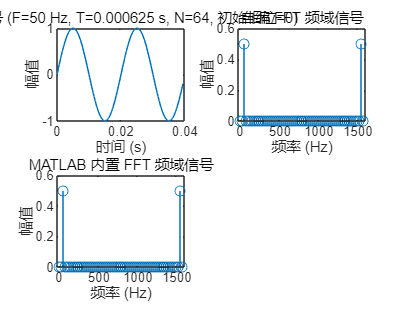

最大差异: 1.1416e-14


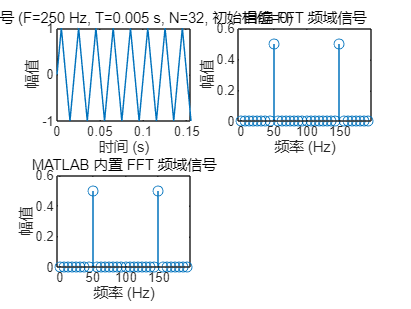

最大差异: 9.7972e-16


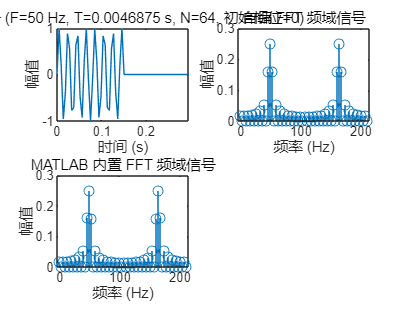

最大差异: 5.8344e-15


% 基-2按时间抽取的FFT算法
function X = FFT_time_extract(x)
    N = length(x);
    if N <= 1
        X = x;
    else
        % 递归调用 FFT 计算
        X_even = FFT_time_extract(x(1:2:end));%分治
        X_odd = FFT_time_extract(x(2:2:end));
        W = exp(-2i*pi*(0:N/2-1)/N); % 旋转因子
        X = [X_even + W .* X_odd, X_even - W .* X_odd];
    end
end

% 比较自编FFT与MATLAB内置FFT结果
function compare_fft(F, T, N, m, zero_padding)
    % 生成信号，带有初始相位m
    t = (0:N-1) * T;
    x = sin(2*pi*F*t + m);
    
    % 补零选项
    if zero_padding
        x = [x, zeros(1, N)]; % 补零至2*N样点
        N = 2 * N; % 更新样点数
    end
    
    % 自编FFT
    X_custom = FFT_time_extract(x);
    
    % MATLAB内置FFT
    X_builtin = fft(x);
    
    % 频率轴
    f = (0:N-1) * (1/(N*T));
    
    % 绘制时域图
    figure;
    subplot(2,2,1);
    plot((0:N-1)*T, x);
    title(['时域信号 (F=', num2str(F), ' Hz, T=', num2str(T), ' s, N=', num2str(N), ', 初始相位=', num2str(m), ')']);
    xlabel('时间 (s)');
    ylabel('幅值');

    % 绘制频域比较图
    subplot(2,2,2);
    stem(f, abs(X_custom)/N);
    title('自编 FFT 频域信号');
    xlabel('频率 (Hz)');
    ylabel('幅值');
    
    subplot(2,2,3);
    stem(f, abs(X_builtin)/N);
    title('MATLAB 内置 FFT 频域信号');
    xlabel('频率 (Hz)');
    ylabel('幅值');
    
    % 比较结果
    diff = max(abs(X_custom - X_builtin));
    disp(['最大差异: ', num2str(diff)]);
end

% 主函数，添加参数输入选择
function main_fft_time()
    disp('请选择参数输入方式：');
    disp('1. 使用默认参数');
    disp('2. 自定义输入参数');
    choice = input('输入您的选择 (1 或 2): ');
    
    if choice == 1
        % 使用默认参数
        run_default_tests_time();
    elseif choice == 2
        % 自定义参数输入
        F = input('信号频率F/hz= ');
        N = input('采样点数N= ');
        T = input('采样时间间隔T/s= ');
        m = input('初始相位= ');
        flag = input('是否补零（1为yes/0为no）= ');
        compare_fft(F, T, N, m, flag);
    else
        disp('无效的选择');
    end
end

% 默认参数测试
function run_default_tests_time()
    % a) F=50Hz, N=32, T=0.000625s, 初始相位=0
    compare_fft(50, 0.000625, 32, 0, 0);

    % b) F=50Hz, N=32, T=0.005s, 初始相位=0
    compare_fft(50, 0.005, 32, 0, 0);

    % c) F=50Hz, N=32, T=0.0046875s, 初始相位=0
    compare_fft(50, 0.0046875, 32, 0, 0);

    % d) F=50Hz, N=32, T=0.004s, 初始相位=0
    compare_fft(50, 0.004, 32, 0, 0);

    % e) F=50Hz, N=64, T=0.000625s, 初始相位=0
    compare_fft(50, 0.000625, 64, 0, 0);

    % f) F=250Hz, N=32, T=0.005s, 初始相位=0
    compare_fft(250, 0.005, 32, 0, 0);

    % g) F=50Hz, N=32, T=0.0046875s, 初始相位=0, 补零
    compare_fft(50, 0.0046875, 32, 0, 1);
end

% 运行按时间抽取FFT测试
main_fft_time();